# Quantitative Methods for Finance

2025 Marina Dolfin

# QMF1_7_Data_Analysys

## Interpolation (filling missing data)

When working with real data, it is very common to encounter missing observations. For example, when downloading prices or returns from online sources, some dates may be absent or reported as *NaN* (Not-a-Number) in MATLAB.

Dealing properly with missing data is essential, as ignoring or mishandling them can distort statistical analysis, correlation measures, or model estimation.

MATLAB provides several dedicated tools and **Live Editor Tasks** specifically designed to handle missing values in a controlled and transparent way.

In this activity, we use one of these tasks — **Fill Missing Data** — to demonstrate different strategies for filling or removing missing values, ensuring that the dataset remains consistent for further analysis.

The task can be accessed interactively through

**Apps → Live Editor Tasks → Fill Missing Data**,

allowing you to visually select the variable to process and choose among various methods:

First import the data from the file 'Data_miss.xlsx)

Data_miss = readtable('Data_miss.xlsx')


Data_miss = 165×12 table
       Date         AAPL      MSFT      NVDA     GOOGL      JPM        GS      HSBC      KO        PG       XOM      SHEL 
    ___________    ______    ______    ______    ______    ______    ______    _____    _____    ______    ______    _____

    02-Jan-2025    243.85       NaN    138.31    189.43       240    574.97    48.68    61.84    165.98    107.31     63.1
    03-Jan-2025    243.36    423.35    144.47    191.79    243.28    580.13    49.07    61.75    165.13    107.86    64.52
    06-Jan-2025       NaN    427.85    149.43    196.87    240.85    583.3

**Using the *****Fill Missing Data***** Task**

Follow these steps to handle missing observations in your dataset:

- Open the **Fill Missing Data** task(*Apps → Live Editor Tasks → Fill Missing Data*).

- Set **Input data** to `Data_miss`.

- Under **Select data**, choose **All supported variables** so that the task processes all price series.

- In the **Display variable** dropdown, select **AAPL** to visualize the effect of the filling method.

- Practise by trying different filling options — such as **linear**, **previous**, **next**, or **moving mean** — and observe how each method reconstructs the missing values.

- When you are satisfied with the method, set the **Output variable name** (in the task options) to `Data_filled`.MATLAB will automatically create a new variable containing the cleaned data.

- Compare the filled data with the original timetable using, for example:

stackedplot(synchronize(Data_miss, Data_filled, "union"))

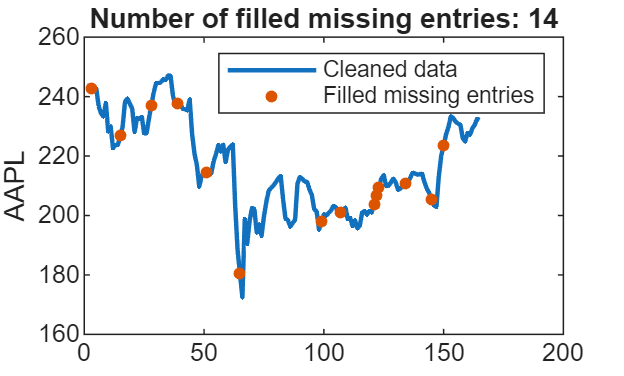

% Fill missing data
[Data_filled,missingIndices] = fillmissing(Data_miss,"linear");

% Display results
figure

% Plot cleaned data
plot(Data_filled.AAPL,SeriesIndex=1,LineWidth=1.5,DisplayName="Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices(:,2)),Data_filled.AAPL(missingIndices(:,2)),".", ...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,2)))


hold off
legend
ylabel("AAPL")
clear missingIndices

title('Raw data')

By default, the `fillmissing` function and the **Clean Missing Data** Live Editor task assume the observations are equally spaced when performing the interpolation. But what if the data points are not equally spaced?

If you have unevenly spaced data, you can specify the spacing of the observations by providing a vector that represents the sampling locations.

You can specify the sampling locations using the drop-down list next to **X-axis**.

Plotting the interpolated values with equal and unequal spacing shows the small differences between the two methods.

For moving window operations with a noncentered window, use a vector `[``kb` `kf``]` to specify the number of backward and forward points to include. `kb` is the number of trailing (backward) points, and `kf` is the number of leading (forward) points.

For example, this command smooths data using a window that includes the current point, 5 trailing points, and 2 leading points.

`dN` `=` `smoothdata``(``d``,``method``,``[``5` `2``])`